# **EEG DURING SLEEP**

### Loading the signal

The 9-hour signal was recorder with a sampling frequency of 512 Hz. The first and the last two minutes were arbitrary cut due to possible misrecordings.

load("record.mat");
EEG = double(record);
clear record
fs_EEG = 512;
EEG = EEG(3*60*fs_EEG:end);
EEG = EEG((length(EEG)/fs_EEG - 2*60)*fs_EEG:-1:1);
N = length(EEG);

### Power Spectrum 

To understand which kind of filters to use PSD was computed with Welch's Method (Hann's Window) with 50% overlap

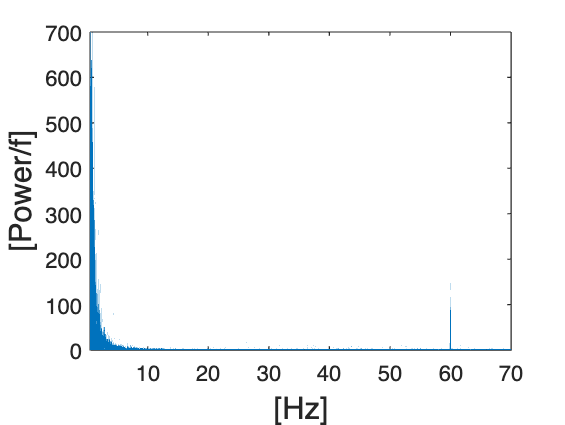

noverlap = 0.5*N;
EEG = detrend(EEG);
[Pxx, freq1] = pwelch(EEG, hanning(length(EEG)), noverlap, [], fs_EEG);

figure
plot(freq1, Pxx)
xlim([0.5,70]);
xlabel('[Hz]', fontsize=14);
ylabel('[Power/f]',fontsize=14);

### Filtering 

We noticed a net infererence at 60Hz, so we design an IIR notch filter. Then, according to literature we extracted the band of interest of EEG

- Low Pass filter at 70 Hz  

- High Pass filter at 0.5 Hz 

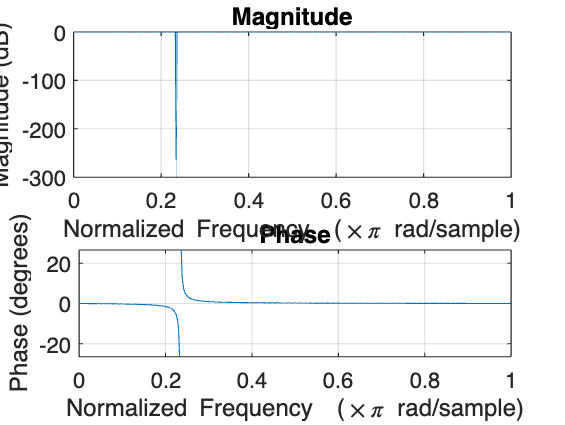

%Notch Filter
[b,a] = iirnotch(60/(fs_EEG/2),0.5/(fs_EEG/2));
EEG = filtfilt(b,a, EEG);

%Filter specs
figure 
freqz(b,a);

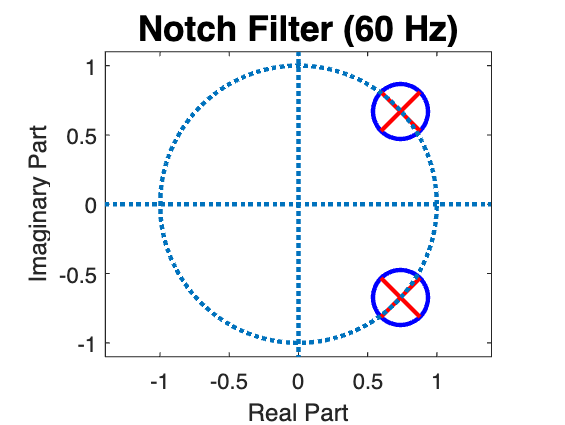

figure 
[hz,hp,hl]=zplane(b,a);
set(hz, markerSize=25, color='b',linewidth=2);
set(hp, markerSize=25, color='r',linewidth=2);
set(hl,linewidth=2)
title('Notch Filter (60 Hz)','FontSize',16)

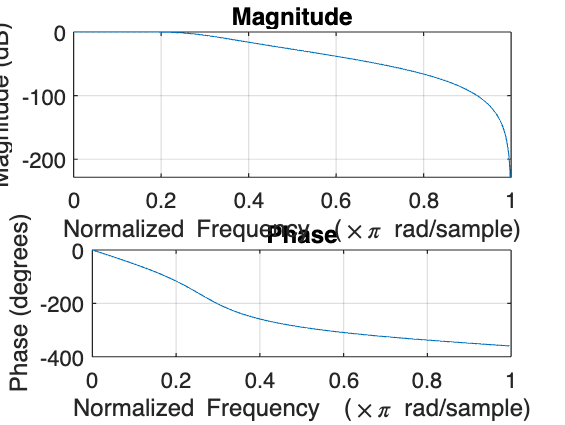

%Low-pass
filter_order = 4;
f_cut = 70;
wc = f_cut/(fs_EEG/2);
[b,a] = butter(filter_order,wc,'low');
EEG = filtfilt(b,a,EEG);

%Filter specs
figure
freqz(b,a);

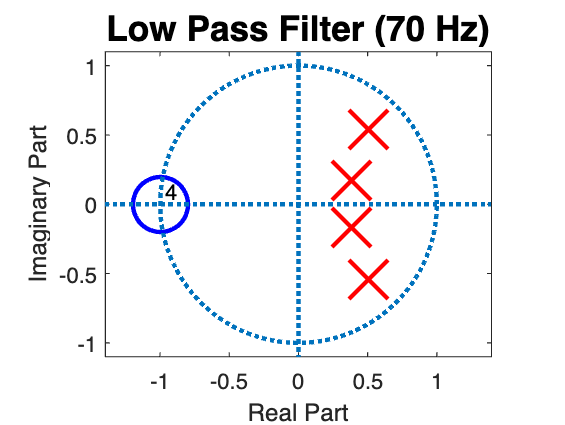

figure 
[hz,hp,hl]=zplane(b,a);

set(hz, markerSize=25, color='b',linewidth=2);
set(hp, markerSize=25, color='r',linewidth=2);
set(hl,linewidth=2)
title('Low Pass Filter (70 Hz)','FontSize',16)

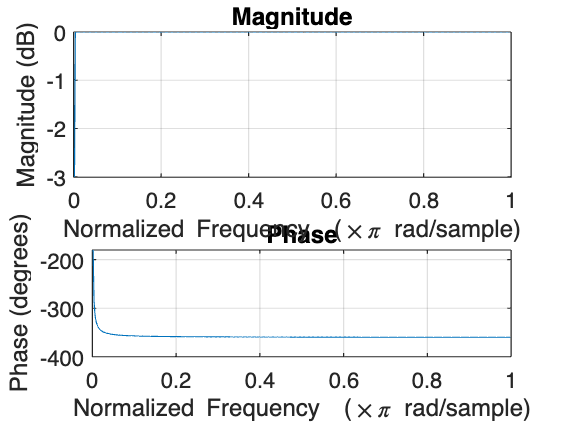

%High-pass
filter_order = 4;
f_cut = 0.5;
wc = f_cut/(fs_EEG/2);
[b,a] = butter(filter_order,wc,'high');
EEG = filtfilt(b,a,EEG);

%Filter specs
figure
freqz(b,a);

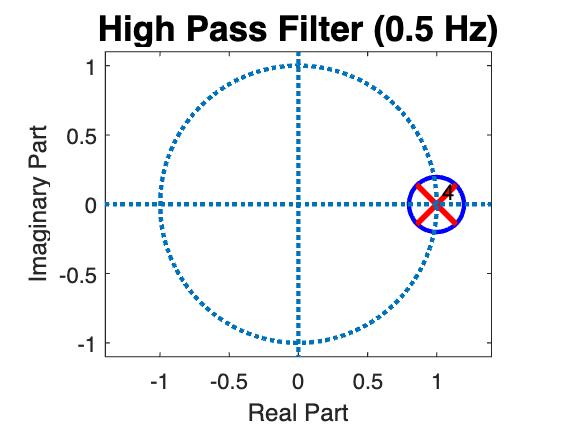

figure 
[hz,hp,hl]=zplane(b,a);
set(hz, markerSize=25, color='b',linewidth=2);
set(hp, markerSize=25, color='r',linewidth=2);
set(hl,linewidth=2)
title('High Pass Filter (0.5 Hz)','FontSize',16)

After filtering we plot again the power spectrum to see the results of pre-processing 

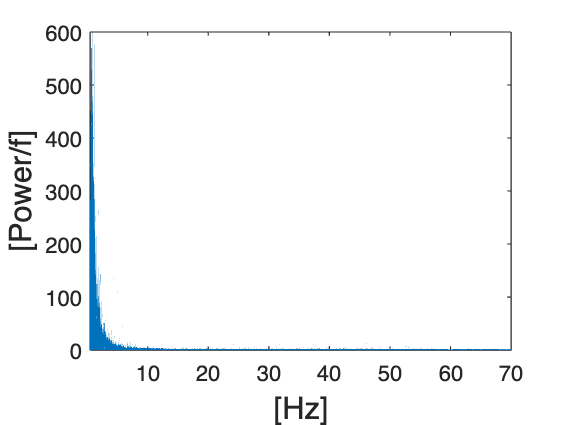

noverlap = 0.5*N;
[Pxx, freq1] = pwelch(EEG, hanning(length(EEG)), noverlap, [], fs_EEG);

figure
plot(freq1, Pxx)
xlabel('[Hz]', fontsize=14);
ylabel('[Power/f]',fontsize=14);
xlim([0.5 70])

### Dividing into epochs and PSD computation

9-hour signal was divided into 30-second epochs to better analyze sleep stages.

lep = 30; %seconds 
ep_samples = lep*fs_EEG; %number of samples for each epoch

%EEG bands
f_vect_high = [8 4 2.5 18];
f_vect_low = [14 8 4 25];
names = ["alpha", "theta", "delta", "beta"];

For each epoch we calculate the PSD of all the frequency content and for each band of interest (alpha, theta, delta). To determine the power of each band we calculated the variance (according to the Parseval Theorem) and to estimate how present is each band of interest, we computed the ratio between the variance of PSD of that band and the variance of the whole PSD.  

PSD for each epoch was computed using Welch's method, with a 20-second overlapping Hann's window.

ep = cell(1, floor(length(EEG)/ep_samples)); %cell array of the epochs
var = cell(floor(length(EEG)/ep_samples), 3); %cell array of the variances
perc = cell(floor(length(EEG)/ep_samples), 3); %cell array of the percentages

for i = 1:floor(length(EEG)/ep_samples)
    %Epochs extraction
    ep{i} = EEG(1+ep_samples*(i-1):ep_samples*(i));
    ep{i} = detrend(ep{i});

    %Whole frequencies PSD with Welch
    noverlap = 20*fs_EEG;
    [Pxx_ep, freq_ep] = pwelch(ep{i}, hanning(ep_samples), noverlap, [], fs_EEG);
    freq1_ep = 0:fs_EEG/length(Pxx_ep):fs_EEG/2;


    for j = 1 : length(f_vect_low)
        filter_order = 4;
        %Low-pass
        f_cut = f_vect_low(j);
        wc = f_cut/(fs_EEG/2);
        [b,a] = butter(filter_order,wc,'low');
        ep_lp = filtfilt(b,a,ep{i});

        %High-pass
        f_cut = f_vect_high(j);
        wc = f_cut/(fs_EEG/2);
        [b,a] = butter(filter_order,wc,'high');
        ep_filt = filtfilt(b,a,ep_lp);

        %PSD with Welch for the j-band 
        noverlap = 20*fs_EEG/2;
        [Pxx, freq] = pwelch(ep_filt, hanning(ep_samples), noverlap, [], fs_EEG);
        
        %Variance and percentage calculation
        var{i,j} = trapz(freq, Pxx);
        perc{i, j} = trapz(freq, Pxx)/trapz(freq_ep, Pxx_ep);
    end
end

var = cell2table(var, 'VariableNames', names);
save("variances.mat", "var");

perc = cell2table(perc, 'VariableNames', names);
save("percentages.mat", "perc");

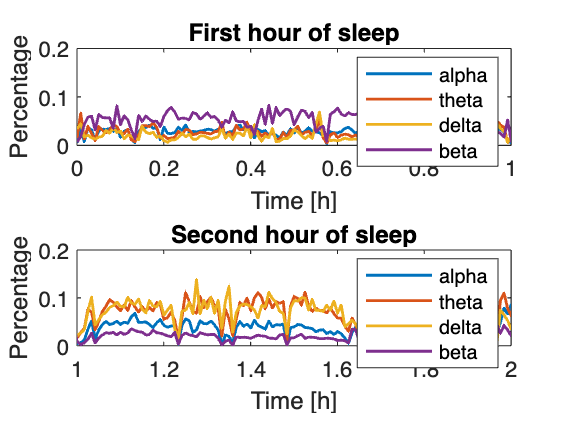

%Plot of the percentages for each frequency band in 
% the first hour and the second one as an example
lim = [0 1];
figure
t = (1:lep:lep*floor(length(EEG)/ep_samples))/3600;
subplot(2,1,1)
plot(t,perc.alpha,'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

hold on
plot(t,perc.theta, 'LineWidth',1.3);
ylim([0,0.2]), 
xlim(lim);

hold on 
plot(t,perc.delta, 'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

hold on 
plot(t,perc.beta, 'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

xlabel('Time [h]')
ylabel('Percentage')
title('First hour of sleep')
legend('alpha', 'theta', 'delta', 'beta')

lim = [1 2];
subplot(2,1,2)
plot(t,perc.alpha,'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

hold on
plot(t,perc.theta, 'LineWidth',1.3);
ylim([0,0.2]), 
xlim(lim);

hold on 
plot(t,perc.delta, 'LineWidth',1.3),
ylim([0,0.4]), 
xlim(lim);

hold on 
plot(t,perc.beta, 'LineWidth',1.3),
ylim([0,0.2]), 
xlim(lim);

xlabel('Time [h]')
ylabel('Percentage')
title('Second hour of sleep')

legend('alpha', 'theta', 'delta', 'beta')

### Sleep stages classification

Sleep stages are characterized by the presence of some certain bands.

For each epoch, we sort the bands, from the less dominant to the predominant one.

domTab = cell(floor(length(EEG)/ep_samples),4);
for i = 1:floor(length(EEG)/ep_samples)

    h = perc{i,:} == min(perc{i,:});
    domTab{i,1} = perc.Properties.VariableNames{h};
    h = perc{i,:} == min(perc{i,:}(perc{i,:}>min(perc{i,:})));
    domTab{i,2} = perc.Properties.VariableNames{h};
    h = perc{i,:} == max(perc{i,:});
    domTab{i,4} = perc.Properties.VariableNames{h};
    h = perc{i,:} == max(perc{i,:}(perc{i,:}<max(perc{i,:})));
    domTab{i,3} = perc.Properties.VariableNames{h};
    
end

Sleep period can be subdivided into five stages: 

- Awake 

- REM

- Stage NREM1

- Stage NREM 2

- Stage NREM 3

stages = zeros(size(domTab,1),1);
for i = 1:3:size(domTab,1)-3
    %awake
    if(isequal(domTab(i,4), {'beta'})) || (isequal(domTab(i,4), {'alpha'}))
        stages(i:i+3) = 4;
    end

    %light-sleep
    if (isequal(domTab(i,4), {'theta'})) && (isequal(domTab(i+1,4), {'theta'}))
        stages(i:i+8) = 2;
    end

    %deep sleep
    if (isequal(domTab(i,4), {'delta'})) && (isequal(domTab(i+1,4), {'delta'}))
        stages(i:i+8) = 1;
    end

    %REM
    if (isequal(domTab(i,4), {'theta'}) && isequal(domTab(i,3), {'alpha'}))
        stages(i:i+8) = 3;
    end
end


%smoothing
for i = 4:size(domTab,1)-3
    if stages(i) == 0
        if stages(i+1) ~= 0
            stages(i) = stages(i+1);
        elseif i>1 && stages(i-1) ~= 0
                stages(i) = stages(i-1);
        else
            stages(i) = stages(i+2);
        end
    end
end

EpTogether = 10;
for i = 1:EpTogether:length(stages)-EpTogether
    count = zeros(5,1);
    for k=1:5
        for j=i:i+EpTogether-1
            if stages(j)==k
                count(k)=count(k)+1;
            end
        end     
    end
    [pp,p]=max(count);
    for j=i:i+EpTogether-1
        stages(j,1)=p;
    end
end


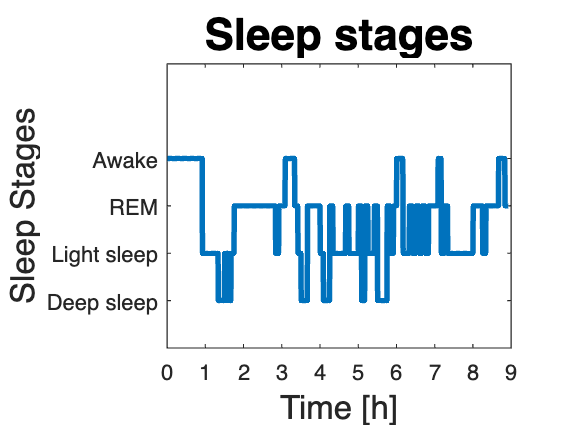

figure 
plot(1:length(stages), stages,'LineWidth',2.5,'Color','#0072BD')
title("Sleep stages", 'FontSize', 20)
xlabel('Time [h]','FontSize',15)
ylabel('Sleep Stages', 'FontSize',15)
set(gca,'YTick',0:4);
yticklabels({'';'Deep sleep';'Light sleep';'REM';'Awake';''})
set(gca,'XTick',0:120:1080);
ylim([0,6]);
xticklabels(0:9)
xlim([0 1080])